% Create individual element
freq = 900e6;
vp = physconst('lightspeed');
lambda = vp/freq;
N = 2;
ucdx = 0.485*lambda;
ucdy = 0.5*lambda;
d = dipole;
d.Length = 0.157;
d.Width = 0.002;

% sweep impendance for freq 800 MHz - 1 GHz in 20 steps
impedance(d,linspace(800e6,1000e6,20));

% Orient the antenna element horizontal, parallel, on same axis
d.TiltAxis = 'Y';
d.Tilt = 90;

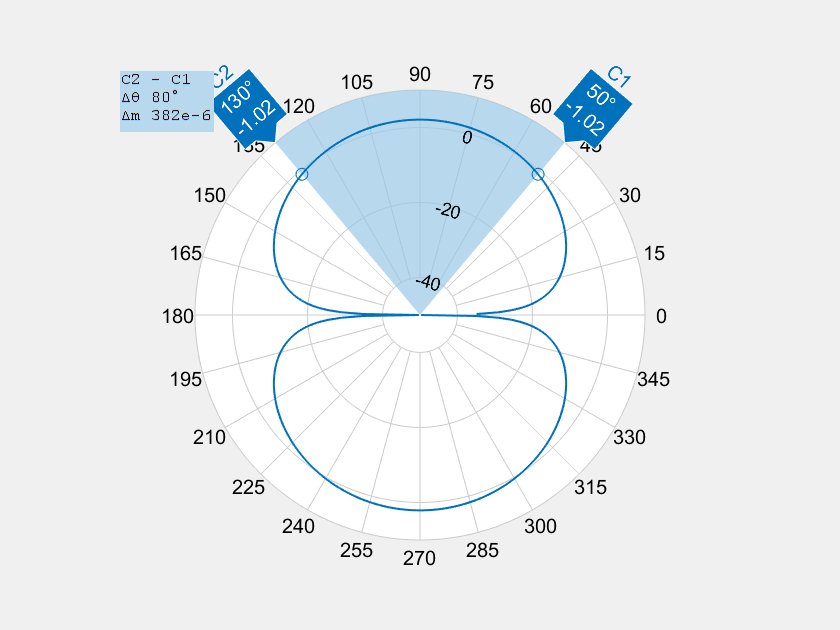

% Plot and calculate beamwidth
beamwidth(d,freq,0,1:1:360);

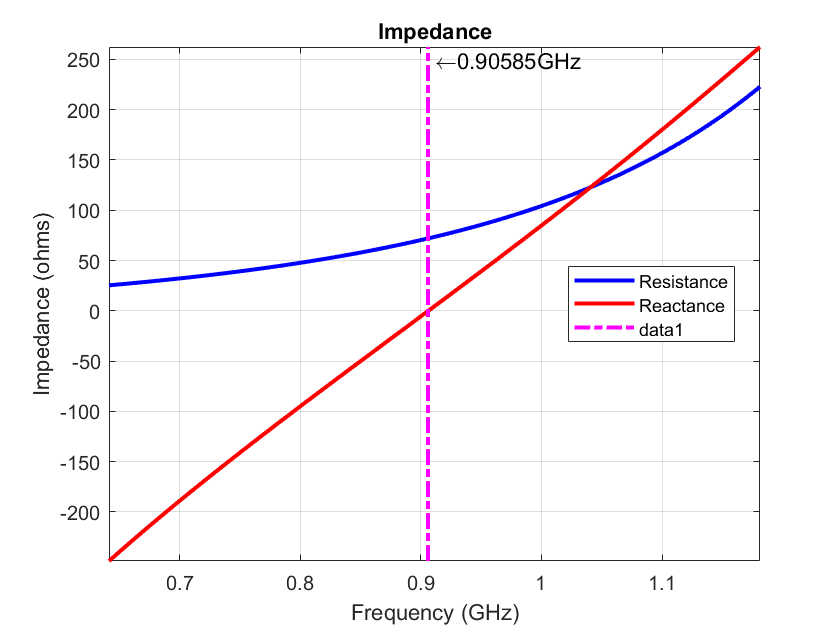

% Use dipole_tuner to sweep for resonant frequency ?
fmin = freq - .05*freq;
fmax = freq + .05*freq;
minX = 0.0001;          % Minimum value of reactance to achieve
trim = 0.0005;          % The amount to shorten the length at each iteration
resonant_dipole = dipole_tuner(d,freq,fmin,fmax,minX,trim);

Z_resonant_dipole = impedance(resonant_dipole,freq)

Z_resonant_dipole = 70.1526 - 6.5062i

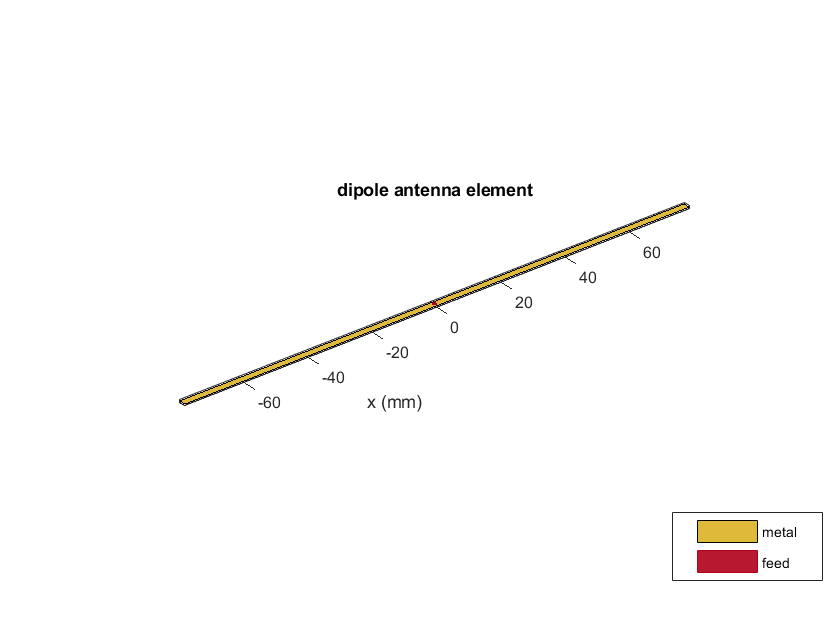

helement = figure;
show(resonant_dipole)
axis tight

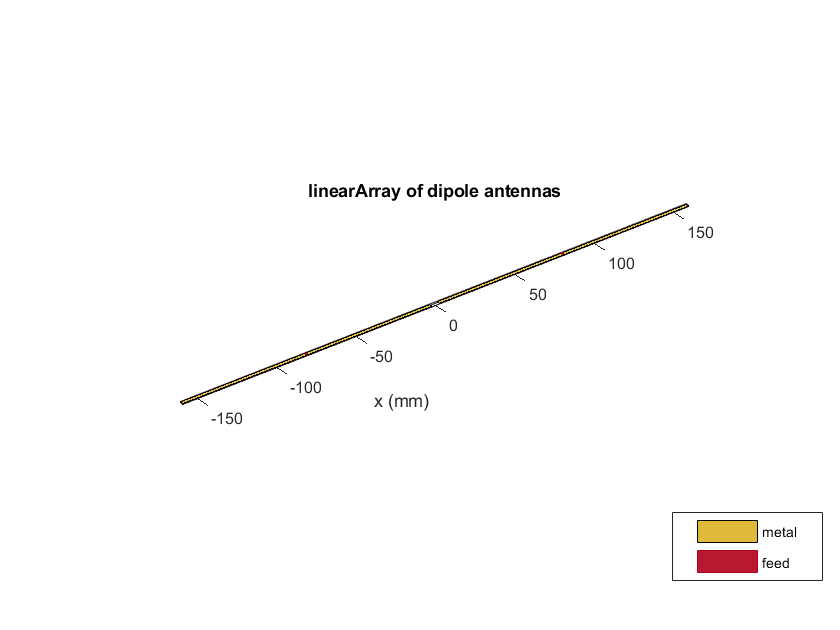

% Create array
dipole_array = linearArray;
dipole_array.Element = resonant_dipole;
dipole_array.NumElements = N;
dipole_array.ElementSpacing = ucdx;
hArray = figure;
show(dipole_array)
axis tight

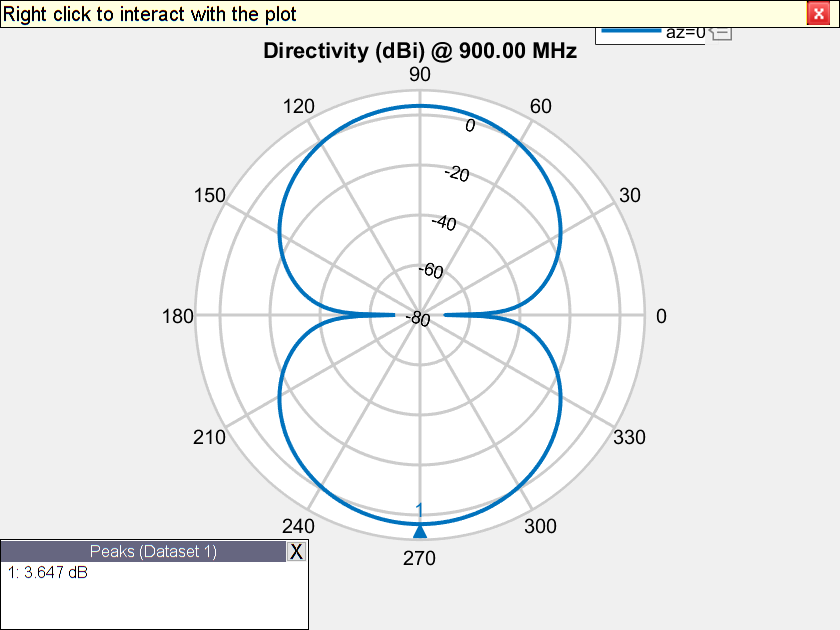

% Polar radiation pattern plot
h(2) = figure;
patternElevation(dipole_array,900e6);

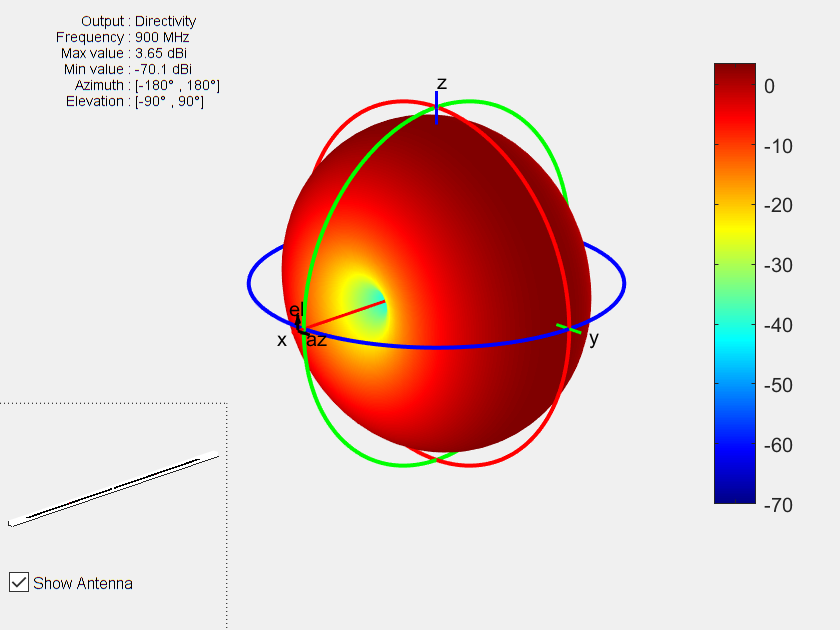

% Show radiation pattern
pattern3Dfig = figure;
pattern(dipole_array,freq)

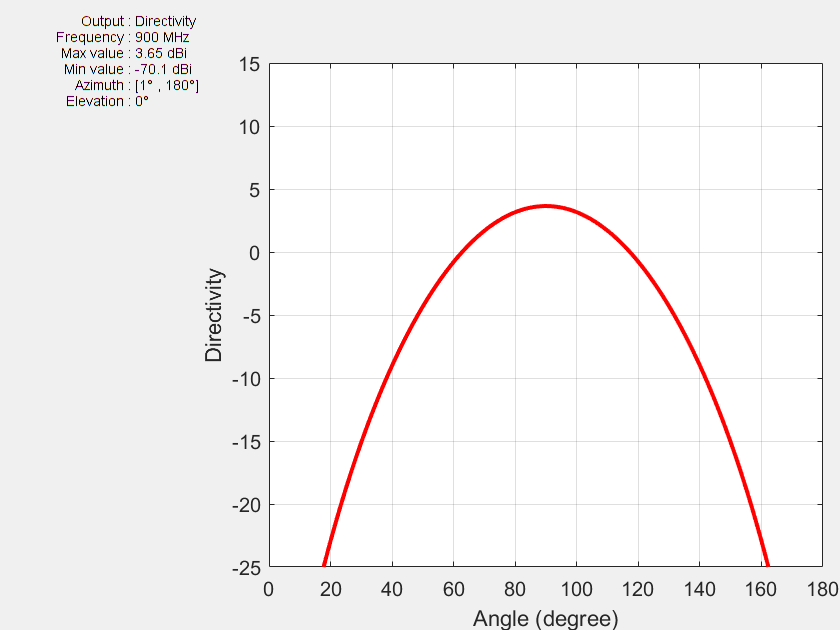

patternazfig1 = figure;
az_angle = 1:0.25:180;
pattern(dipole_array,freq,az_angle,0,'CoordinateSystem','rectangular')
axis([0 180 -25 15])